clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

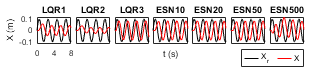

load("data\fig4_lqresnperform.mat");
figsize = [5,15,8.2,1.8];

t1 = 0:0.01:40;
t2 = 0:0.01:45;
tend = 801;

% lw = 0.6;
lw = 0.4;
fs = 7;

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gcf,'Visible','on');

positions = cell(1,7);
axs = cell(1,7);
for i = 1:7
    positions{i} = [0.06+0.125*(i-1) 0.35 0.11 0.4];
end
axs{1} = subplot(1,7,1);
axs{1}.Position = positions{1};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), lqr1xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
ylabel('X (m)');
xticks([0 t1(tend)/2 t1(tend)]);
axs{1}.XTickLabelRotation = 0;
title('LQR1', 'FontSize', fs);

axs{2} = subplot(1,7,2);
axs{2}.Position = positions{2};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), lqr2xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('LQR2', 'FontSize', fs);

axs{3} = subplot(1,7,3);
axs{3}.Position = positions{3};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), lqr3xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('LQR3', 'FontSize', fs);

axs{4} = subplot(1,7,4);
axs{4}.Position = positions{4};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), esn10xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('ESN10', 'FontSize', fs);
xlabel('t (s)');

axs{5} = subplot(1,7,5);
axs{5}.Position = positions{5};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), esn20xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('ESN20', 'FontSize', fs);

axs{6} = subplot(1,7,6);
axs{6}.Position = positions{6};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), esn50xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('ESN50', 'FontSize', fs);

axs{7} = subplot(1,7,7);
axs{7}.Position = positions{7};

p1 = plot(t1(1:tend), rsin(1:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t1(1:tend), esn500xsin(1:tend), 'r');
ylim([-0.12 0.12]);
xlim([0 t1(tend)]);
xticks([]);
yticks([]);
title('ESN500', 'FontSize', fs);

leg = legend('X_r', 'X', 'NumColumns',2);
leg.ItemTokenSize = [10 10];
leg.Position = [0.829,0.1,0.1,0.1];
leg.FontSize = 6;

for i = 1:7
    axs{i}.Position = axs{i}.Position + [0.06 0 0 0];
end

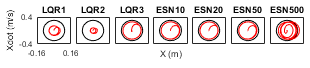

ylimit = [-0.4 0.4];
xlimit = [-0.16 0.16];
tbegin = 1;
tend = 801;

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gcf,'Visible','on');

positions = cell(1,7);
axs = cell(1,7);
for i = 1:7
    positions{i} = [0.06+0.125*(i-1) 0.35 0.11 0.4];
end
axs{1} = subplot(1,7,1);
axs{1}.Position = positions{1};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr1xsin(tbegin:tend), lqr1xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
ylabel('Xdot (m/s)');
xticks(xlimit);
yticks(ylimit);
axs{1}.XTickLabelRotation = 0;
title('LQR1', 'FontSize', fs);

axs{2} = subplot(1,7,2);
axs{2}.Position = positions{2};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr2xsin(tbegin:tend), lqr2xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR2', 'FontSize', fs);

axs{3} = subplot(1,7,3);
axs{3}.Position = positions{3};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr3xsin(tbegin:tend), lqr3xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR3', 'FontSize', fs);

axs{4} = subplot(1,7,4);
axs{4}.Position = positions{4};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn10xsin(tbegin:tend), esn10xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN10', 'FontSize', fs);
xlabel('X (m)');

axs{5} = subplot(1,7,5);
axs{5}.Position = positions{5};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn20xsin(tbegin:tend), esn20xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN20', 'FontSize', fs);

axs{6} = subplot(1,7,6);
axs{6}.Position = positions{6};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn50xsin(tbegin:tend), esn50xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN50', 'FontSize', fs);

axs{7} = subplot(1,7,7);
axs{7}.Position = positions{7};

p1 = plot(rsin(tbegin:tend), rdotsin(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn500xsin(tbegin:tend), esn500xdotsin(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN500', 'FontSize', fs);

for i = 1:7
    axs{i}.Position = axs{i}.Position + [0.06 0 0 0];
end

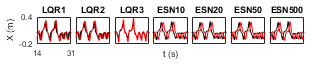

tbegin = 1401;
tend = 3101;
ylimit = [-0.2 0.4];
xlimit = [t2(tbegin) t2(tend)];

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gcf,'Visible','on');

positions = cell(1,7);
axs = cell(1,7);
for i = 1:7
    positions{i} = [0.06+0.125*(i-1) 0.35 0.11 0.4];
end
axs{1} = subplot(1,7,1);
axs{1}.Position = positions{1};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), lqr1xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
ylabel('X (m)');
xticks(xlimit);
yticks(ylimit);
axs{1}.XTickLabelRotation = 0;
title('LQR1');

axs{2} = subplot(1,7,2);
axs{2}.Position = positions{2};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), lqr2xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR2');

axs{3} = subplot(1,7,3);
axs{3}.Position = positions{3};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), lqr3xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR3');

axs{4} = subplot(1,7,4);
axs{4}.Position = positions{4};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), esn10xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN10');
xlabel('t (s)');

axs{5} = subplot(1,7,5);
axs{5}.Position = positions{5};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), esn20xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN20');

axs{6} = subplot(1,7,6);
axs{6}.Position = positions{6};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), esn50xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN50');

axs{7} = subplot(1,7,7);
axs{7}.Position = positions{7};

p1 = plot(t2(tbegin:tend), rlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(t2(tbegin:tend), esn500xlorenz(tbegin:tend), 'r');
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN500');

for i = 1:7
    axs{i}.Position = axs{i}.Position + [0.06 0 0 0];
end

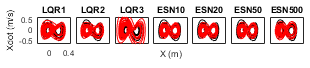

tbegin = 1;
tend = 4501;
ylimit = [-0.65 0.65];
xlimit = [-0.25 0.45];
lw = 0.4;

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gcf,'Visible','on');

positions = cell(1,7);
axs = cell(1,7);
for i = 1:7
    positions{i} = [0.06+0.125*(i-1) 0.35 0.11 0.4];
end
axs{1} = subplot(1,7,1);
axs{1}.Position = positions{1};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr1xlorenz(tbegin:tend), lqr1xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
ylabel('Xdot (m/s)');
% xticks([t2(tbegin) t2(tend)]);
title('LQR1');

axs{2} = subplot(1,7,2);
axs{2}.Position = positions{2};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr2xlorenz(tbegin:tend), lqr2xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR2');

axs{3} = subplot(1,7,3);
axs{3}.Position = positions{3};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(lqr3xlorenz(tbegin:tend), lqr3xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('LQR3');

axs{4} = subplot(1,7,4);
axs{4}.Position = positions{4};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn10xlorenz(tbegin:tend), esn10xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN10');
xlabel('X (m)');

axs{5} = subplot(1,7,5);
axs{5}.Position = positions{5};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn20xlorenz(tbegin:tend), esn20xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN20');

axs{6} = subplot(1,7,6);
axs{6}.Position = positions{6};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn50xlorenz(tbegin:tend), esn50xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN50');

axs{7} = subplot(1,7,7);
axs{7}.Position = positions{7};

p1 = plot(rlorenz(tbegin:tend), rdotlorenz(tbegin:tend), 'k');
p1.LineWidth = lw;
hold on;
p2 = plot(esn500xlorenz(tbegin:tend), esn500xdotlorenz(tbegin:tend), 'r');
p2.LineWidth = lw;
ylim(ylimit);
xlim(xlimit);
xticks([]);
yticks([]);
title('ESN500');

for i = 1:7
    axs{i}.Position = axs{i}.Position + [0.06 0 0 0];
end